## Note: this file will take a preprocessed EEG dataset, determine an appropriate baseline, and feed it into a Gaussian Mixture Model (GMM)

## read in filtered data

% load in the filtered dataset
%allEDFs_filtered = allEDFs

## BASELINE 


% find index of first instance of "intubat" (intubation)
intubation_Index = find_indx(allEDFs_filtered, 'intubat')

intubation_Index = 259585

% conv to datetime
%intubation_Index = allEDFs_filtered.data{'EEG'}.Properties.RowTimes(intubation_Index)
%TODO: error with using datetime and current format: datetime+1 does not
%give next index, but 
%% SOLVED: take difference between two indices, store that, and add that to datetime to increment it an index
% find index of first instance of "incis" (incision)
incision_Index = find_indx(allEDFs_filtered, 'incis')

incision_Index = 678529

%incision_Index = allEDFs_filtered.data{'EEG'}.Properties.RowTimes(incision_Index)
% run function to determine start index for each EEG channel
channels = allEDFs_filtered.data{'EEG'}.Properties.VariableNames;
if length(channels) ~= 8
    fprintf("Warning: number of channels does not equal 8");
end
table_size = size(allEDFs_filtered.data{'EEG'}); % determine size of table for for loop



## test that there are no alerts being annotated in baseline region

count1 = count_searchkey(allEDFs_filtered,'intub', 'alert', 'eeg');
count2 = count_searchkey(allEDFs_filtered, 'incis', 'alert','eeg');
if (abs(count2 - count1) > 0)
    error("critical alert: EEG alert found in baseline determination window");
end

% ** we are not currently using the start index for the analysis, so it is
% commented out to save computation time

% start_index = nan(1,table_size(1,2));
% for k = 1:length(channels) 
%     % TODO: once "EEG_PreProcess.mlx" is complete, modify method for determining start index. 
%     % all of those repeated values should become nan so we just need to take values after that point.
%     start_index(1,k) = baseline_mean(table_size, allEDFs_filtered, channels(1,k));
% end
% start_index % check for baseline start

% check that there is not a lot of variance between start_index values. too
% large of a difference could indicate a problem with the baseline
% determination values and would need to be evaluated on a case-by-case
% basis
% diffs = diff(start_index);
% diffs = max(abs(diffs(diffs >= 0)));
% if (diffs > 5)
%     error("large variance among baseline start indices detected. largest difference was determined to be " + diffs)
% end

## baseline mean determination (single value/channel)

% baseline_preIntubation = nan(1,8);
% baseline_postIntubation = nan(1,8);
% baseline_Total = nan(1,8);
% for i = 1:table_size(1,2)
%     baseline_preIntubation(1,i) = mean(allEDFs_filtered.data{'EEG'}{start_index(1,i):intubation_Index, channels(1,i)},'omitnan');  
%     baseline_postIntubation(1,i) = mean(allEDFs_filtered.data{'EEG'}{intubation_Index:incision_Index, channels(1,i)},'omitnan');  
%     baseline_Total(1,i) = mean(allEDFs_filtered.data{'EEG'}{start_index(1,i):incision_Index, channels(1,i)},'omitnan');
% end
% baseline_preIntubation
% baseline_postIntubation
% baseline_Total

## baseline mean determination (15 sec window/channel)


% 15 second windows
    % data from baseline regions is divided into 15 second windows and then
    % the mean is calculated to create one 15 second array per channel

rows_per_record = allEDFs_filtered.info{'EEG'}.NumSamples(1);    
sample_rate = rows_per_record/seconds(allEDFs_filtered.info{'EEG'}.DataRecordDuration);   
window_size = sample_rate * 15;

%preintubation_mean_baseline_window = mean_baseline_windowed(start_index, intubation_Index, allEDFs_filtered, window_size, channels)
%postintubation_mean_baseline_window = mean_baseline_windowed(intubation_Index, incision_Index, allEDFs_filtered, window_size, channels)
%total_mean_baseline_window = mean_baseline_windowed(start_index, incision_Index, allEDFs_filtered, window_size, channels)  

## baseline window determination (3D - for GMM)

%window_preintubation_baseline = windowed_data(start_index, intubation_Index, allEDFs_filtered, window_size,channels)
window_postintubation_baseline = windowed_data(intubation_Index, incision_Index, allEDFs_filtered, window_size,channels) 

window_postintubation_baseline = window_postintubation_baseline(:,:,1) =

   -3.0977   -4.9556    9.1003   -2.8465    3.8921    2.6967    1.6003    6.3135
   -4.9252   -9.3566    8.3693   -3.2119    1.0825   -4.3845   -4.4988    6.2754
   -6.5165  -12.7678    6.1688   -5.1688   -2.8236   -8.5343   -9.6308    5.0571
   -7.8566  -14.7247   -8.7171   -6.6307   -7.7044  -13.9100  -13.2932   -2.5114
  -10.0572  -17.4125  -11.6485   -7.8490  -15.0293  -20.1308  -13.4531   -6.9049
  -11.8846  -19.3618  -11.6638   -8.3363  -20.6486  -25.2628  -12.2272  -10.3237
  -14.0851  -21.3186   -9.9582   -8.3516  -21.9887  -27.0902   -7.3465  -12.5166
  -16.2780  -23.5115   -7.2703   -7.4988  -21.7450  -27.0674   -6.1282  -13.3770
  -16.5217  -23.9989   -8.0013   -6.2805  -18.8136  -25.3618   -9.5470  -13.3846
  -16.4074  -23.7552  -10.6891   -5.7932  -15.1511  -21.9430  -12.9658  -11.7932
  -15.3110  -20.5877  -12.6384   -5.6561  -11.2450  -17.5496  -13.9404   -9.4785
  -13.3617  -15.9430  -12.8897   -5

## ANALYSIS 

% Note: from hospital team: abnormal events are annotated as alerts when duration
% of event exceeds 1 min

% from hospital team: abnormal events are observed when one or both
% hemishperes stray from baseline

## analysis window determination

window_analysis = windowed_data(incision_Index+1, size(allEDFs_filtered.data{'EEG'}(:,1)), allEDFs_filtered, window_size,channels)

window_analysis = window_analysis(:,:,1) =

       NaN   51.3518  101.7810       NaN       NaN -160.7508  171.4894       NaN
       NaN   76.7453  100.9282       NaN       NaN -143.1695  116.7963       NaN
       NaN   80.6514  130.2278       NaN       NaN -125.5958  171.4894  199.1368
 -165.6468   49.4025  132.1771  190.2281       NaN -137.3142       NaN  167.8879
 -170.0402   52.3264  100.9282  135.5426       NaN -127.5451       NaN  113.1947
 -138.7913   52.1741   46.2426   88.6692       NaN -125.7176  191.5073   66.3214
 -127.0730   20.9252  -78.7606   82.8063       NaN -135.4791  162.2077   66.4432
 -158.3219   18.9760 -149.0706   69.1387       NaN -130.1111  -56.5422  -58.5523
  -33.3263   32.6436 -149.9234  -55.8645 -100.6439 -149.6416  -87.7911  -97.6211
 -103.6363   79.5245 -153.8295  -81.2504 -112.3622 -161.3600   68.4610  -85.9027
   83.8646  -45.4787       NaN  -51.9584  -81.1134 -166.7356  146.5832   39.1005
       NaN  -92.3520       NaN -169.1417  137.6365 -153.0604     

## gaussian mixture model

Fs = allEDFs_filtered.info{'EEG'}.NumSamples(1,1)/seconds(allEDFs_filtered.info{'EEG'}.DataRecordDuration(1,1));   % sampling rate
L = length(window_analysis)

L = 1920

N = L % end point

N = 1920

f = (Fs*(0:((L-1)/2))/L); % frequency
transforms_analysis = fft(window_analysis, N, 1)/L; % returns each band being == 1Hz
single_sided_transform = transforms_analysis(1:L/2, :, :);
plot(f, single_sided_transform(:,1,1))

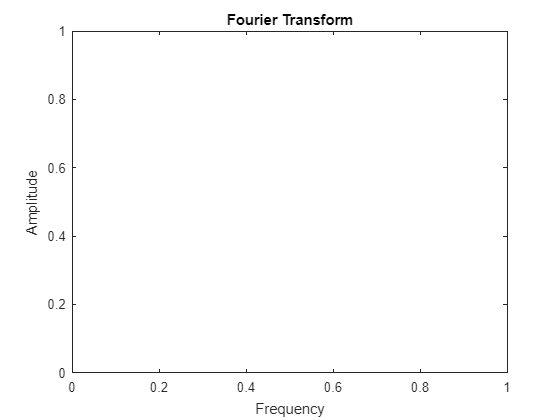

xlabel('Frequency')
ylabel('Amplitude')
title('Fourier Transform')

% spectral bands
% delta_analysis = spectral_bandpower(window_analysis, [1 3], Fs);
% delta_baseline = spectral_bandpower(window_postintubation_baseline, [1 3], Fs);
% theta_analysis = spectral_bandpower(window_analysis, [4 7], Fs);
% theta_baseline = spectral_bandpower(window_postintubation_baseline, [4 7], Fs);
% alpha_analysis = spectral_bandpower(window_analysis, [8 12], Fs);
% alpha_baseline = spectral_bandpower(window_postintubation_baseline, [8 12], Fs);
% beta_analysis = spectral_bandpower(window_analysis, [13 20], Fs);
% beta_baseline = spectral_bandpower(window_postintubation_baseline, [13 20], Fs);
% gamma_analysis = spectral_bandpower(window_analysis, [30 100], Fs); 
% gamma_baseline = spectral_bandpower(window_postintubation_baseline, [30 100], Fs);

% for each 15 second window, for each channel compute delta (1-3Hz) theta
% (4-7Hz) alpha (8-12Hz) beta (13-20Hz) gamma (30-100Hz) (spectral) - 40 measurements for each window (40 X #15-second
% windows you have), then feed it into gaussian mixture model
spectral_bands = struct('delta', {spectral_bandpower(window_postintubation_baseline, [1 3], Fs,channels),spectral_bandpower(window_analysis, [1 3], Fs,channels)}, ...
    'theta',{spectral_bandpower(window_postintubation_baseline, [4 7], Fs,channels), spectral_bandpower(window_analysis, [4 7], Fs,channels)}, ...
    'alpha', {spectral_bandpower(window_postintubation_baseline, [8 12], Fs,channels), spectral_bandpower(window_analysis, [8 12], Fs,channels)}, ...
    'beta', {spectral_bandpower(window_postintubation_baseline, [13 20], Fs,channels), spectral_bandpower(window_analysis, [13 20], Fs,channels)}, ...
    'gamma', {spectral_bandpower(window_postintubation_baseline, [30 100], Fs,channels), spectral_bandpower(window_analysis, [30 100], Fs,channels)});

% for easy indexing
baseline = 1;
analysis = 2;

% renaming table variable names in order to concactenate
% matlab does not allow columns in a table to share the same variable
% names, so the new format is "spectralValue_originialColumnName"

% NOTE: i couldnt figure out how to index the table in spectral_bands by the name
% of the in the struc (delta, theta, etc.) saved as a variable because I originially wanted to
% do this with 2 for loops, so it will just be like this loops unless i can figure it out :/
spectral_names = fieldnames(spectral_bands);
new_column_names = [channels; channels; channels;channels;channels];
for i = 1:length(spectral_names)
    for j = 1:length(channels)
        new_column_names(i,j) = strcat(spectral_names{i},'_',new_column_names(i,j));
    end
end
spectral_bands(baseline).delta = renamevars(spectral_bands(baseline).delta,channels,new_column_names(1,:));
spectral_bands(analysis).delta = renamevars(spectral_bands(analysis).delta,channels,new_column_names(1,:));
spectral_bands(baseline).theta = renamevars(spectral_bands(baseline).theta,channels,new_column_names(2,:));
spectral_bands(analysis).theta = renamevars(spectral_bands(analysis).theta,channels,new_column_names(2,:));
spectral_bands(baseline).alpha = renamevars(spectral_bands(baseline).alpha,channels,new_column_names(3,:));
spectral_bands(analysis).alpha = renamevars(spectral_bands(analysis).alpha,channels,new_column_names(3,:));
spectral_bands(baseline).beta = renamevars(spectral_bands(baseline).beta,channels,new_column_names(4,:));
spectral_bands(analysis).beta = renamevars(spectral_bands(analysis).beta,channels,new_column_names(4,:));
spectral_bands(baseline).gamma = renamevars(spectral_bands(baseline).gamma,channels,new_column_names(5,:));
spectral_bands(analysis).gamma = renamevars(spectral_bands(analysis).gamma,channels,new_column_names(5,:));



% concactenate for GMM evaluation
spectral_bands_concat = struct('baseline',[spectral_bands(baseline).delta, spectral_bands(baseline).theta, ...
    spectral_bands(baseline).alpha, spectral_bands(baseline).beta, spectral_bands(baseline).gamma],...
    'analysis', [spectral_bands(analysis).delta, spectral_bands(analysis).theta, ...
    spectral_bands(analysis).alpha, spectral_bands(analysis).beta,spectral_bands(analysis).gamma])

spectral_bands_concat = struct with fields:
    baseline: [219×40 table]
    analysis: [1007×40 table]


concat_size = size(spectral_bands_concat.baseline);

rng('default') % for reproducibility
eva = evalclusters(table2array(spectral_bands_concat.baseline),'kmeans','CalinskiHarabasz','KList',1:concat_size(1,2))

eva =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 219
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40]
    CriterionValues: [NaN 234.5540 261.2186 232.9497 209.6132 199.3804 182.0421 171.5235 159.2112 155.0789 143.3394 136.2928 127.0185 121.2429 116.9161 115.4136 108.5895 104.2707 98.9231 99.4753 92.1001 92.1244 88.7382 87.6426 80.4086 85.6005 79.6739 … ]
           OptimalK: 3


k = eva.OptimalK

k = 3

% NOTE: fitgmdist requires stastics and machine learning toolbox
try
GMModel = fitgmdist(table2array(spectral_bands_concat.baseline), k)
catch exception
    disp('There was an eror fitting the GMM')
    error = exception.message
    fprintf('regularize data and try again')
    GMModel = fitgmdist(table2array(spectral_bands_concat.baseline),k,'RegularizationValue',0.0001)
    % TODO: tune regularization value
    % NOTE: if repeatedly getting errors, look into optimizing
    % regularization values/seed
end

There was an eror fitting the GMM


error = 'Ill-conditioned covariance created at iteration 2.'

regularize data and try again

GMModel = 

Gaussian mixture distribution with 3 components in 40 dimensions




[P_baseline, nlogL_baseline] = posterior(GMModel, table2array(spectral_bands_concat.baseline))

P_baseline =          0    0.0000    1.0000
         0    0.0000    1.0000
         0    0.9948    0.0052
         0    1.0000    0.0000
         0    1.0000    0.0000
         0    0.0000    1.0000
         0    0.0000    1.0000
         0    1.0000    0.0000
         0         0    1.0000
         0    0.0000    1.0000


nlogL_baseline = 1.4868e+04

[P_analysis, nlogL_analysis] = posterior(GMModel, table2array(spectral_bands_concat.analysis))

P_analysis =     1.0000    0.0000    0.0000
    1.0000    0.0000    0.0000
    1.0000    0.0000    0.0000
    1.0000    0.0000    0.0000
    1.0000    0.0000    0.0000
    1.0000    0.0000    0.0000
    1.0000    0.0000    0.0000
    1.0000    0.0000    0.0000
    1.0000    0.0000    0.0000
    1.0000    0.0000    0.0000


nlogL_analysis = 1.0317e+05

% TODO: check P_baseline to make sure that all windows fit cleanly in one
% of k componenents (error) https://www.mathworks.com/help/stats/tune-gaussian-mixture-models.html
for q = 1:length(P_baseline)
    if (max(P_baseline(q,:)) < 0.9)
        x = ['warning: poor tuning of GMM for window ', q];
        disp(x)
    end
end
% TODO: find windows with low probability of being in any of k dimensions
threshold = 1; % TODO: tune this threshold
% NOTE: outliers are calculated by checking if there not one single clear
% cluster that the window fits into
outliers = struct('data', [], 'datetime',[]); % preallocate outlier_array
for m = 1:length(P_analysis)
    if ~(max(P_analysis(m,:)) > threshold)
        % display relevant windows with timestamped data
        [start_time, end_time] = get_datetime_for_window(allEDFs_filtered, incision_Index + 1, size(allEDFs_filtered.data{'EEG'}(:,1)), m, window_size);
        outliers.datetime = [start_time end_time];
        outliers.data = P_analysis(m,:); 
    end
end

Unable
to
perform
assignment
because
brace
indexing
is not
supported
for
variables
of
this
type.

flag = 0; % track if outliers are found (default false) 
if (isnan(outliers))
    fprintf('no outliers found')
    outliers = 'no outliers found'
else 
    flag = 1; % indicate that outliers are found 
end
% TODO: count instances of "Alert" relevant to EEG after incision_Index
% Note: this is currently written to detect ALL alerts annotated after
% incision_Index.
% TODO: update functionality to indicate only EEG alerts
alert_count = count_searchkey(allEDFs_filtered, 'incis', 'alert', 'eeg');
if (alert_count == 0)
    fprintf("no EEG alerts found after baseline");
end




% TODO: output report for clinical team


% (principal component analysis)

%NOTE: GMM requires Statistics and Machine Learning Toolbox